defaultDir = 'M:\Bergles Lab Data\Papers\In Vivo Paper'; %change if in a different location
cd(defaultDir);
addpath(genpath('MATLAB Functions'));
cd('Cover');




## Generate sine waves for cover image

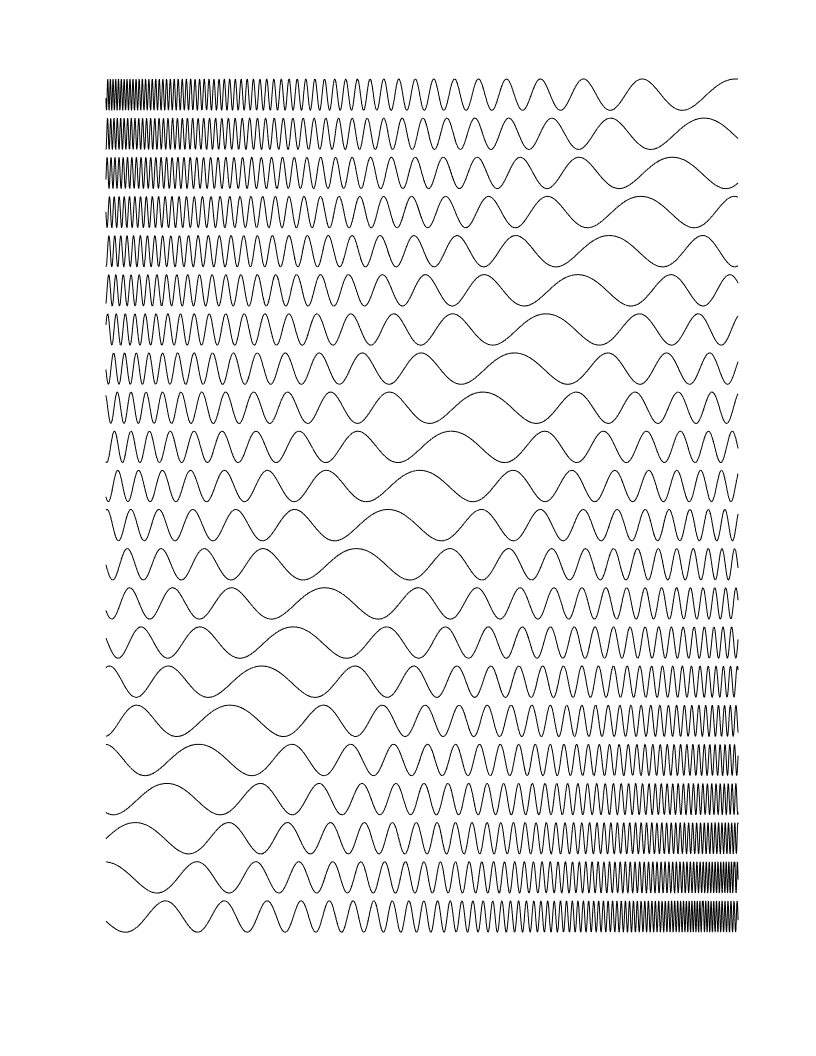


t = 0:0.001:9.98; 
figure;
y = chirp(t,0.5,10,25,'logarithmic');
y = [y fliplr(y)];
y = [y fliplr(y)];
t = 1:1:size(y,2);
for i = 1:22
    plot(t - 500*(i-1), y-(2.5*(i-1)),'Color','k'); hold on;
end
xlim([10000 20000]);
ylim([-54 1])
plot(y,'Color','k')
axis off; box off;
figQuality(gcf,gca,[8.5 11]);
export_fig('.\EPS Panels\coversine','-eps')

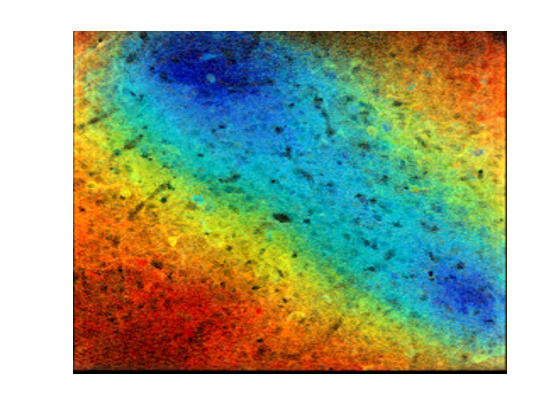

file = '..\Figure 2  - 2P\Data\Snap25GC6s_SR101\Animal 1_170714_004\2Pcorr.mat';
load(file);
corrImg = data.corrImg;
corrRGB = zeros(256,256,3);
%original
corrRGB(:,:,3) = corrImg(:,:,1)*.8 + corrImg(:,:,3)/max(max(corrImg(:,:,1) + corrImg(:,:,3)));
corrRGB(:,:,2) = (corrImg(:,:,5) + corrImg(:,:,3))/max(max(corrImg(:,:,5) + corrImg(:,:,3)));
corrRGB(:,:,1) = corrImg(:,:,6)/max(max(corrImg(:,:,6)));
%altered
corrRGB(:,:,1) = corrImg(:,:,6) + corrImg(:,:,5)*.5 + corrImg(:,:,4)*1.1;
corrRGB(:,:,2) = corrImg(:,:,4)*.8 + corrImg(:,:,3)*.4 + corrImg(:,:,2)*.7; % )/max(max(corrImg(:,:,5)  ));
corrRGB(:,:,3) = corrImg(:,:,1)*.8 +corrImg(:,:,2)*.7;

final = imresize(corrRGB,16);


figure; imagesc(final);
box off; axis off;

imwrite(final,['.\Data\ICCorrMap_2p.bmp']);